clearvars

% Init param
M = zeros(12, 1);
for i = 1:length(M)
    M(i) = 2^i;
end

N = zeros(20, 1);       % No se utiliza
for i = 1:length(N)
    N(i) = i;
end

N_fixed = 2;
[z,w] = GaussHermite_Locations_Weights(N_fixed);
M_fixed = 1024;         % No se utiliza
SNR = 1.0;

rho = 0;
max_rho = 1;
delta = 0.001;
% E0_values = [];  % Pel display
% rho_values = []; % Pel display

maxE0 = -Inf;
best_rho = -1; current_rho = 0.5;

% Per E0(1) - fors
E0_1 = zeros(length(M), 1);
time_E = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    E0_1(i) = E0_v2(current_rho, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_E(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per E0(1) - matrius
E0_1_matrix = zeros(length(M), 1);
time_Ematrix = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    [Q, pi_, G] = matrix_generator(N_fixed, q, x, w, z, SNR);
    tic; % Time starts 
    E0_1_matrix(i) = E0_matrix(Q, pi_, G, current_rho);
    elapsed_time = toc; % Time ends
    time_Ematrix(i) = elapsed_time;
end

% -------------------------------------------------------------
% Per F0(1) - fors
F0_1 = zeros(length(M), 1);
time_F = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    tic; % Time starts 
    F0_1(i) = F0(current_rho, N_fixed, q, x, w, z, SNR);
    elapsed_time = toc; % Time ends
    time_F(i) = elapsed_time;
end


% -------------------------------------------------------------
% Per F0(1) - matrius
F0_1_matrix = zeros(length(M), 1);
time_Fmatrix = zeros(length(M), 1);

for i = 1:length(M)
    [x, q]= PAM_generator(M(i)); % for equiprobable symbols
    [Q, pi_, G] = matrix_generator(N_fixed, q, x, w, z, SNR);
    tic; % Time starts 
    F0_1_matrix(i) = F0_matrix(Q, pi_, G, current_rho);
    elapsed_time = toc; % Time ends
    time_Fmatrix(i) = elapsed_time;
end

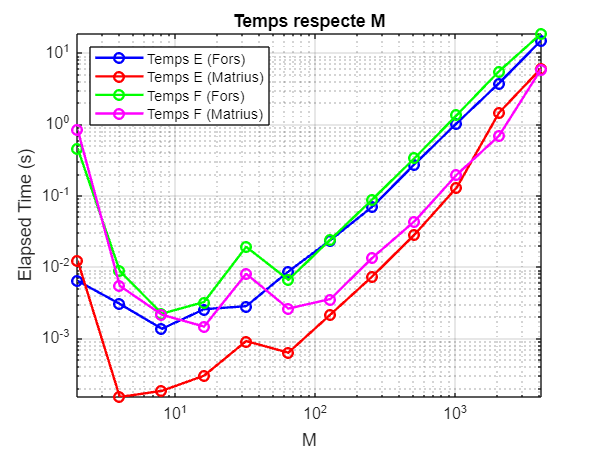

% Display
lim_y = time_E(length(time_E));
if lim_y < time_Ematrix(length(time_Ematrix))
    lim_y = time_Ematrix(length(time_Ematrix));
end
if lim_y < time_F(length(time_F))
    lim_y = time_F(length(time_F));
end
if lim_y < time_Fmatrix(length(time_Fmatrix))
    lim_y = time_Fmatrix(length(time_Fmatrix));
end


% Gràfic
figure;

% Gráfica fors ---- E
loglog(M, time_E, 'o-', 'LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Temps E (Fors)');

hold on;

% Gráfica matrius ---- E matrix
loglog(M, time_Ematrix, 'o-', 'LineWidth', 1.5, 'Color', 'r', 'DisplayName', 'Temps E (Matrius)');

% Gráfica fors ---- F
loglog(M, time_F, 'o-', 'LineWidth', 1.5, 'Color', 'g', 'DisplayName', 'Temps F (Fors)');

% Gráfica matrius ---- F matrix
loglog(M, time_Fmatrix, 'o-', 'LineWidth', 1.5, 'Color', 'm', 'DisplayName', 'Temps F (Matrius)');

grid on;
xlabel('M');
ylabel('Elapsed Time (s)'); 
title('Temps respecte M');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

% Llegenda
legend('show', 'Location', 'northwest');

hold off;

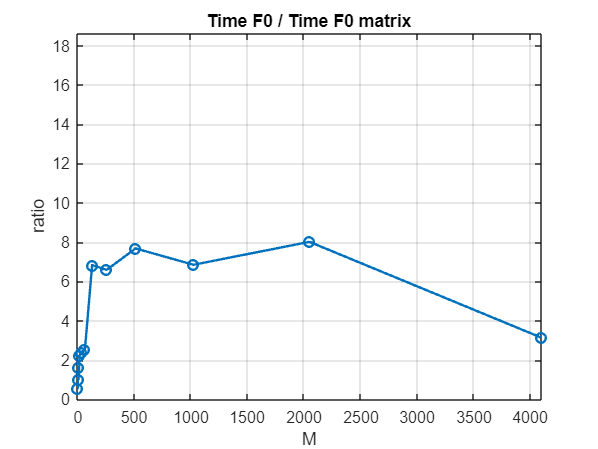

% time F vs time F matrix
r = time_F./time_Fmatrix;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time F0 / Time F0 matrix');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

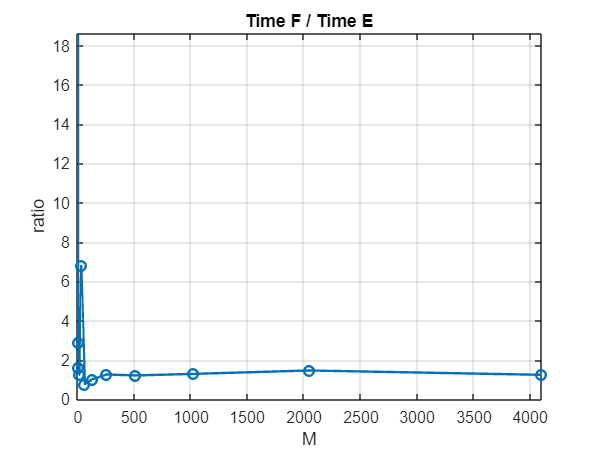


% time E vs time F
r = time_F./time_E;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time F / Time E');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

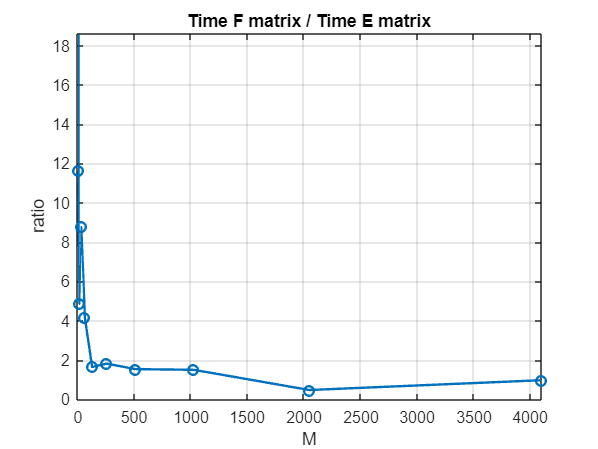


% time E matrix vs time F matrix
r = time_Fmatrix./time_Ematrix;
plot(M, r, 'o-', 'LineWidth', 1.5);
grid on;
xlabel('M');
ylabel('ratio'); 
title('Time F matrix / Time E matrix');
ylim([0 lim_y]);
xlim([0 M(length(M))]);

% % Exemple
% [x, q]= PAM_generator(M(2));
% 
% [F0_1, F0p_1, F02p_1] = F0(1, 2, q, x, w, z, SNR)
% E0_1 = 2^(-E0(1, 2, q, x, w, z, SNR));
% E0_1_prima = -F0p_1/(log(2)*F0_1);
% 
% [Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);
% [F0_1_matriu, F0p_1_matriu, F02p_1_matriu] = F0_matrix(Q, pi_, G, 1)
% E0_1_matriu = E0_matrix(Q, pi_, G, 1);



   0.354189779831742
   0.340067599525657
   0.339169537697576
   0.338946707750180
   0.338891106263449
   0.338877213302358
   0.338873740538464
   0.338872872377473
   0.338872655339103
   0.338872601079628
   0.338872587514766
   0.338872584123552



   0.354189779831742
   0.340067599525657
   0.339169537697576
   0.338946707750180
   0.338891106263448
   0.338877213302359
   0.338873740538465
   0.338872872377474
   0.338872655339104
   0.338872601079628
   0.338872587514768
   0.338872584123548



% disp(E0_1_matrix)
% disp(E0_1)




